# Laboratorio - Analisis y simulacion de robot industrial 

## 1.Localizacion de ruta 

De acuerdo al grafico de la siguiente figura se crea la trayectoria a trozos en un plano XY que posteriormente sera rotado y transladado al espacio de trabajo del robot.

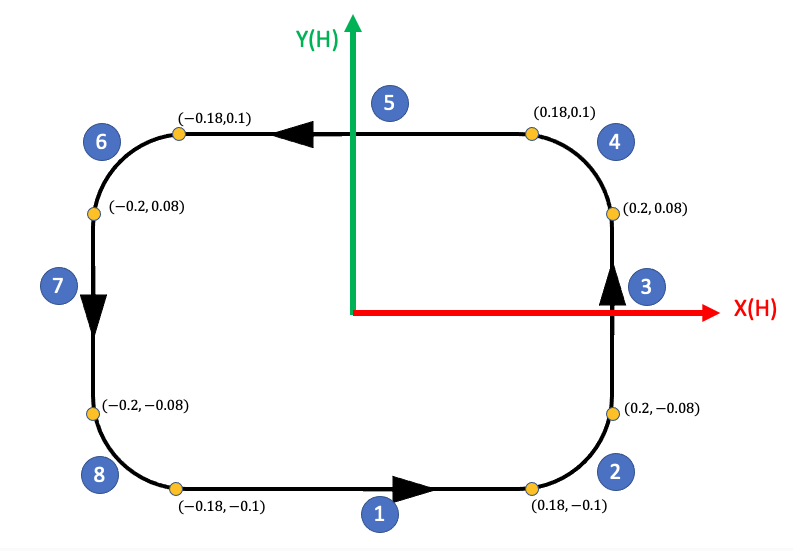

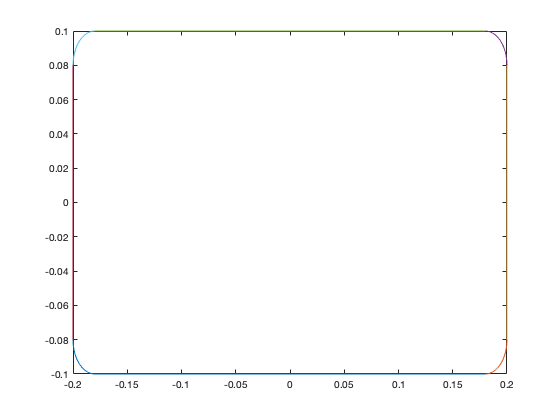

clc
clear
close all

a = 0.18; %distancia en x
b = 0.1;  %distancia en y
c = 0.08; %centro en y de los semicirculos
r = 0.02; %radio 

%%Ruta 1
x = -a:0.01:a;
len = size(x);
y = -b*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = R1;

figure()
plot(x,y);
hold on

%%Ruta 2
t = 3*pi/2:pi/20:2*pi;
x = 0.02*cos(t)+a;
y = 0.02*sin(t)-c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);
%%Ruta 3
y = -c:0.01:c;
len = size(y);
x = (a+r)*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 4
t = 0:pi/20:pi/2;
x = 0.02*cos(t)+a;
y = 0.02*sin(t)+c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 5
x = -a:0.01:a;
len = size(x);
y = b*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 6
t = pi/2:pi/20:pi;
x = 0.02*cos(t)-a;
y = 0.02*sin(t)+c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 7
y = -c:0.01:c;
len = size(y);
x = -(a+r)*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 8
t = pi:pi/20:3*pi/2;
x = 0.02*cos(t)-a;
y = 0.02*sin(t)-c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];

traye = [traye,R1];
plot(x,y);

hold off

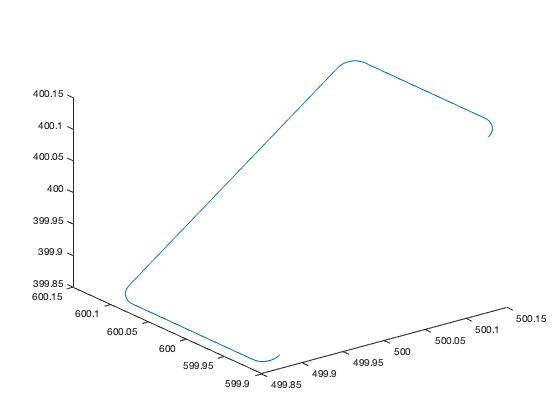


%Matriz de Rotacion
R = [1/sqrt(2),0,-1/sqrt(2);
     0        ,1,0         ;
     1/sqrt(2),0, 1/sqrt(2)];


% Desplazamiento
x = 500;
y = 600;
z = 400;

%% Rotacion y dezplazamiento de la trayectoria

len = size(traye);
for i = 1:len(2)
    traye(1:3,i) = R*traye(1:3,i);
end

traye(1,:) = x + traye(1,:);
traye(2,:) = y + traye(2,:);
traye(3,:) = z + traye(3,:);

figure
plot3(traye(1,:),traye(2,:),traye(3,:))

## 2.Caracteristicas y modelo del robot

- Imagen del robot. https://www.robots.com/robots/fanuc-lr-mate-200ib

http://geek.nmt.edu/~bruder/final_project_files/Fanuc%20LR%20Mate_200ib_200ib_3l.pdf

			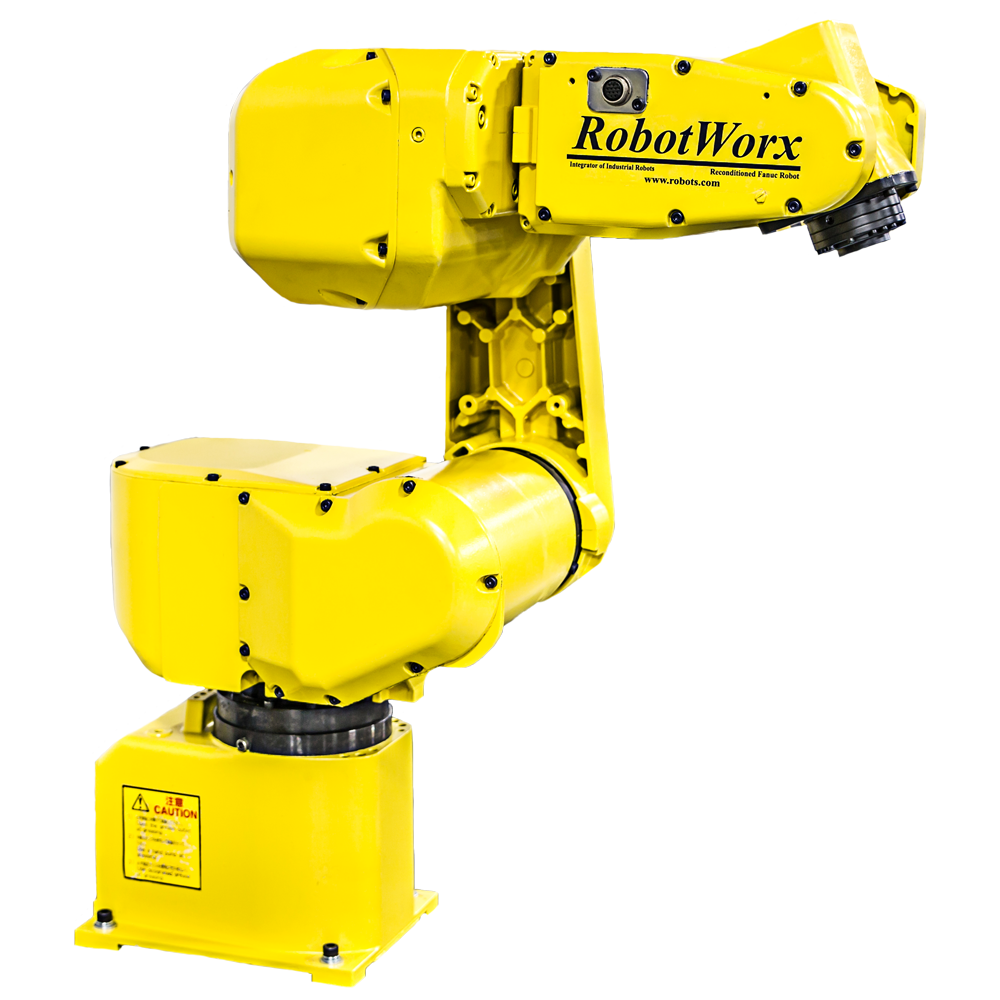		

2. Capacidad de carga = 5 kg.

3. Alcance vertical y horizontal. 

H-Reach: 7000 mm			

4. Repetibilidad. = **± 0.04mm**

5. Grafica(s) de espacio alcanzable.

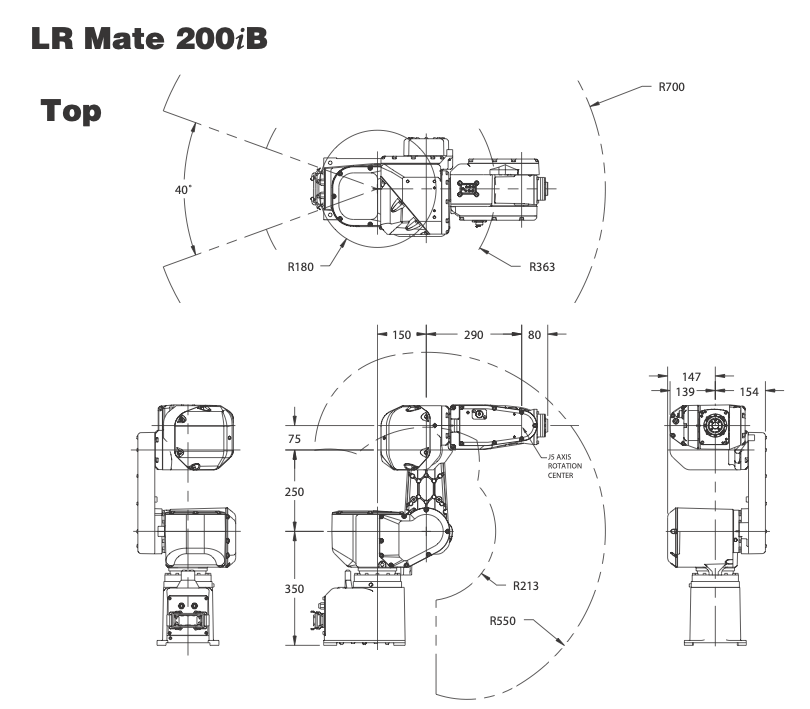

6. Tabla de parametros DH.

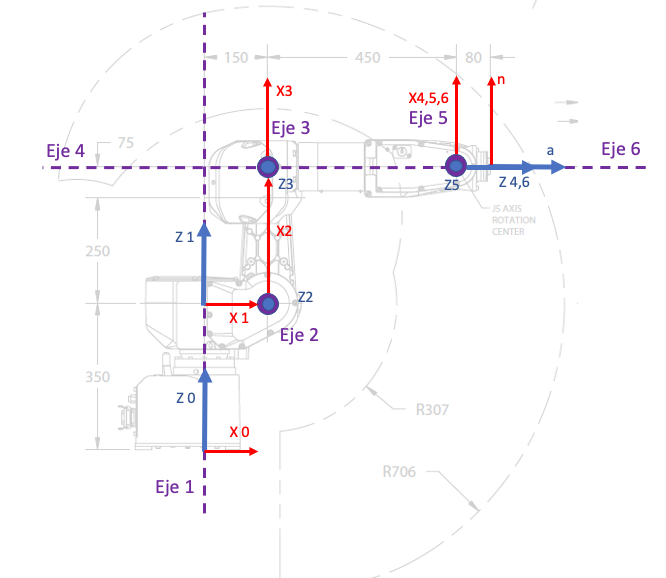

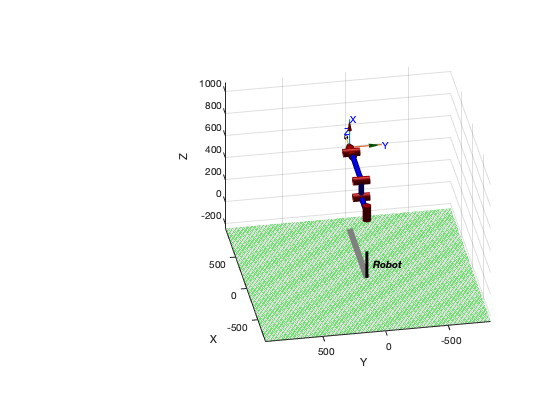

clc;clear;close all
l0 = 350; l1 = 250; l2 = 150; l3 = 450;l4 = 80;
ws= [-70 80 -70 80 -20 90]*12;
plot_options = {'workspace',ws,'scale',0.5,'view',[-100 30], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L(1) = Link('revolute'  ,'alpha', 0,    'a',   0, 'd',  l0,'offset',0,'qlim', [-8*pi/9 8*pi/9],   'modified');
L(2) = Link('revolute'  ,'alpha', pi/2, 'a',  l1, 'd',   0,'offset',pi/2, 'qlim',  [-7*pi/36 5*pi/6],   'modified');
L(3) = Link('revolute'  ,'alpha', 0,    'a',  l2, 'd',   0,'offset',0, 'qlim',  [-11*pi/18 103*pi/90],   'modified');
L(4) = Link('revolute'  ,'alpha',  pi/2,'a',   0, 'd',  l3,'offset',  0, 'qlim',    [-19*pi/18 19*pi/18],   'modified');
L(5) = Link('revolute'  ,'alpha', -pi/2,'a',   0, 'd',   0,'offset',  0, 'qlim',    [-2*pi/3 2*pi/3],   'modified');
L(6) = Link('revolute'  ,'alpha', pi/2, 'a',   0, 'd',   0,'offset',  0, 'qlim',    [-2*pi 2*pi],   'modified');

Robot = SerialLink(L,'name','Robot','plotopt',plot_options);
Robot.tool = [1,0,0,0;
              0,1,0,0;
              0,0,1,l4;
              0,0,0,1];
Robot.teach()

7. Que software utiliza el fabricante para diseño de celdas o programacion. 

FANUC ROBOGUIDE SIMULATION SOFTWARE

## PARTE 2	

### 6. Iniciando

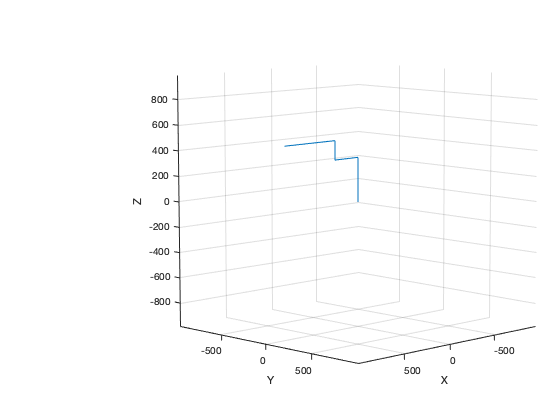

ans =   Axes (Primary) with properties:

             XLim: [-983 983]
             YLim: [-983 983]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [205.7548 56.6871 306.1935 324.6626]
            Units: 'pixels'

  Show all properties


MTH01 = double(L(1).A(0));
MTH02 = double(L(2).A(0));
MTH03 = double(L(3).A(0));
MTH04 = double(L(4).A(0));
MTH05 = double(L(5).A(0));
MTH06 = double(L(6).A(0));
Efec = double(Robot.tool);

robotRST = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt1.HomePosition = 0;
setFixedTransform(jnt1,MTH01);
body1.Joint = jnt1;

addBody(robotRST,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt2.HomePosition = 0;
setFixedTransform(jnt2,MTH02);
body2.Joint = jnt2;

addBody(robotRST,body2,'body1')

body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt3.HomePosition = 0;
setFixedTransform(jnt3,MTH03);
body3.Joint = jnt3;

addBody(robotRST,body3,'body2')

body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt4.HomePosition = 0;
setFixedTransform(jnt4,MTH04);
body4.Joint = jnt4;

addBody(robotRST,body4,'body3')

body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt5.HomePosition = 0;
setFixedTransform(jnt5,MTH05);
body5.Joint = jnt5;

addBody(robotRST,body5,'body4')

body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');
jnt6.HomePosition = 0;
setFixedTransform(jnt6,MTH06);
body6.Joint = jnt6;

addBody(robotRST,body6,'body5')

bodyEndEffector = rigidBody('endeffector');
setFixedTransform(bodyEndEffector.Joint,Efec);
addBody(robotRST,bodyEndEffector,'body6');

%%addVisual(body,"Mesh",filename)
% Robot2 = loadrobot("fanucLRMate200ib")
% showdetails(Robot2)

show(robotRST)

### 7. Modelo geometrico directo			

- Halle el modelo geometrico directo de su robot asignado usando MTH.

syms theta1 theta2 theta3 theta4 theta5 theta6
MTH01 = (L(1).A(theta1));
MTH12 = (L(2).A(theta2));
MTH23 = (L(3).A(theta3));
MTH34 = (L(4).A(theta4));
MTH45 = (L(5).A(theta5));
MTH56 = (L(6).A(theta3));
Efec = Robot.tool;

threshold = 0.0000001;
MTHef = simplify(MTH01*MTH12*MTH23*MTH34*MTH45*MTH56);
MTHef = MTHef*Efec

%MTHef = mapSymType(MTHef,'rational', @(x) piecewise(abs(x)<=threshold, 0, x))

2. Haciendo uso del modelo cinematico directo obtenga los valores de posicion y de orientacion en coordenadas generalizadas del efector final de su robot asignado para los siguientes valores articulares: 

%q1 = [0.5,0.2,0.4,0.5,0,1.5];
q1 = [1,1,1,1,1,1];
q2 = [-pi/2,0.3,0,pi/2,0.4,1.2];
q3 = [0,1,-0.5,2,1,0.5];
q4 = [-1,-0.3,-pi/5,0.4,0.2,1];

x1 = subs(MTHef.T(),[theta1 theta2 theta3 theta4 theta5 theta6],q1)

$$x1 = \left(\begin{array}{cccc} 0.9619 & 0.1086 & 0.2510 & -14.2243\\ 0.2019 & 0.3369 & -0.9196 & -126.9940\\ -0.1844 & 0.9353 & 0.3021 & 864.3968\\ 0 & 0 & 0 & 1 \end{array}\right)$$

x2 = subs(MTHef.T(),[theta1 theta2 theta3 theta4 theta5 theta6],q2)

$$x2 = \left(\begin{array}{cccc} -0.9211 & -3.4652e-17 & -0.3894 & -31.1535\\ 0.3720 & -0.2955 & -0.8799 & -705.9672\\ -0.1151 & -0.9553 & 0.2722 & 648.0599\\ 0 & 0 & 0 & 1 \end{array}\right)$$

x3 = subs(MTHef.T(),[theta1 theta2 theta3 theta4 theta5 theta6],q3)

$$x3 = \left(\begin{array}{cccc} -0.7625 & 0.0802 & 0.6420 & 570.0549\\ -0.6307 & 0.1297 & -0.7651 & -61.2118\\ -0.1446 & -0.9883 & -0.0483 & 642.9250\\ 0 & 0 & 0 & 1 \end{array}\right)$$

x4 = subs(MTHef.T(),[theta1 theta2 theta3 theta4 theta5 theta6],q4)				

$$x4 = \left(\begin{array}{cccc} 0.5586 & -0.7604 & 0.3313 & 331.2158\\ -0.4395 & -0.6102 & -0.6592 & -527.2932\\ 0.7034 & 0.2226 & -0.6750 & 79.0234\\ 0 & 0 & 0 & 1 \end{array}\right)$$

3. Haga uso de las funciones de cinematica directa de ambos toolboxes y compruebe los resultados anteriores. 

**Peter corke**

Robot.fkine(q1)

 

ans = 
    0.9619    0.1086    0.2510    -14.22
    0.2019    0.3369   -0.9196      -127
   -0.1844    0.9353    0.3021     864.4
         0         0         0         1


Robot.fkine(q2)

 

ans = 
   -0.3338    0.8585   -0.3894    -31.15
   -0.1406   -0.4538   -0.8799      -706
   -0.9321   -0.2389    0.2722     648.1
         0         0         0         1


Robot.fkine(q3)

 

ans = 
   -0.3445    0.6849    0.6420     570.1
   -0.2316    0.6007   -0.7651    -61.21
   -0.9098   -0.4123   -0.0483     642.9
         0         0         0         1


Robot.fkine(q4)

 

ans = 
   -0.7912   -0.5140    0.3313     331.2
   -0.5839    0.4738   -0.6592    -527.3
    0.1818   -0.7150   -0.6750     79.02
         0         0         0         1


**RST**

%robotRST.DataFormat = 'row';
getTransform(robotRST,q1,'base','endeffector')

ans =     0.9619    0.2019   -0.1844  198.7093
    0.1086    0.3369    0.9353 -764.1260
    0.2510   -0.9196    0.3021 -374.3497
         0         0         0    1.0000


getTransform(robotRST,q2,'base','endeffector')

ans =    -0.3338   -0.1406   -0.9321  494.3863
    0.8585   -0.4538   -0.2389 -138.8121
   -0.3894   -0.8799    0.2722 -809.7255
         0         0         0    1.0000


getTransform(robotRST,q3,'base','endeffector')

ans =    -0.3445   -0.2316   -0.9098  767.0983
    0.6849    0.6007   -0.4123  -88.6069
    0.6420   -0.7651   -0.0483 -381.7998
         0         0         0    1.0000


getTransform(robotRST,q4,'base','endeffector')

ans =    -0.7912   -0.5839    0.1818  -60.1800
   -0.5140    0.4738   -0.7150  476.5966
    0.3313   -0.6592   -0.6750 -404.0059
         0         0         0    1.0000


4. Compare los metodos. 

5. Elija uno de los metodos anteriormente usados y desarrolle una GUI que permita mover cada articulacion mediante controles tipo Slider, visualizar el robot y la posicion del efector final. 

6. En el informe incluya capturas de pantalla verificando las posiciones EF y las articulaciones. 

## 8. Modelo Geometrico Inverso 			

- Determine el modelo geometrico inverso del robot asignado haciendo uso de la metodologıa explicada en clase. 

Utilizando la aproximacion de desacople cinematico, se realizan los siguiente esquemas para determinar la cinematica inversa de la posicion.

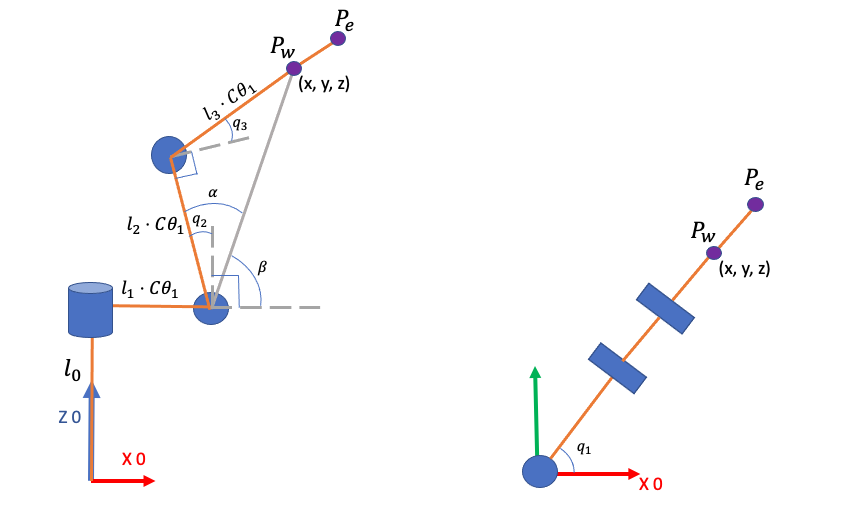

La posicion de la articulacion 1 se puede hallar facilemente usando la vista del plano XY:

 
$$\theta_1 = atan2(y,x)$$
    

Ahora desde el pano ZX, a partir de la vista proyectada del mecanismo se halla el vector la distancia $r$:


$$r^2 = (x-l_1 \cdot C\theta_1 )^2 + (z-l_0)^2$$


Usando la ley del coseno se halla la posicion de la articulacion 3 ($\theta_3$):


$$cos(\theta_3 + \pi/2) = \frac{ (l_3\cdot C\theta_1)^2 + (l_2\cdot C\theta_1)^2 }{-2(l_3\cdot C\theta_1)(l_2\cdot C\theta_1)}$$



$$sen(\theta_3) = \frac{l_3^2 + l_2^2}{2l_2l_3}$$


Para hallar la poscion de la articulacion 2  ($\theta_2
$) es necesario hallar los angulos $\alpha$ y $\beta$:


$$cos(\alpha) = \frac{(l_2 \cdot C\theta_1)^2 + r^2}{-2(l_2\cdot C\theta_1)r}$$



$$\beta = atan2( z - l_0, x-C\theta_1 \cdot l_1)$$


La posicion de la articulacion 2 ($\theta_2$) es:


$$\theta_2 = \alpha + \beta -\frac{\pi}{2}$$
 

2. En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones. 

3. Haga uso de las funciones del RVC para hallar la cinematica inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox explique: 

¿Cual es la diferencia entre estas funciones? 

¿Cual debe usar para su robot y por que? (Revise la documentacion del Toolbox)

4. Haga uso del RST para hallar la cinematica inversa de su robot asignado y compruebe los resultados anteriores. Compare los metodos. 

5. Calcule la configuracion del robot para las siguientes posturas de la herramienta. Proponga 4 posturas (x,y,z,roll,pitch,yaw)′ que esten dentro del espacio de trabajo y determine la configuracion del manipulador y complete la tabla 2. 